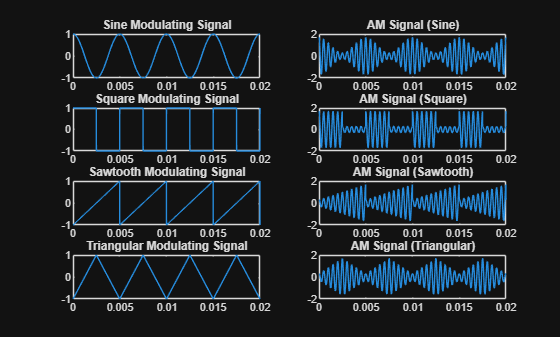

clc;
clear;
close all;

%% PARAMETERS
fs = 100000;          % Sampling frequency
t = 0:1/fs:0.02;      % Time vector

fc = 2000;            % Carrier frequency
Ac = 1;               % Carrier amplitude

fm = 200;             % Modulating frequency
mu = 0.7;             % Modulation index

%% CARRIER SIGNAL
carrier = Ac*cos(2*pi*fc*t);

%% MODULATING SIGNALS
m1 = cos(2*pi*fm*t);        % Sine wave
m2 = square(2*pi*fm*t);     % Square wave
m3 = sawtooth(2*pi*fm*t);   % Sawtooth wave
m4 = sawtooth(2*pi*fm*t,0.5); % Triangular wave

%% AM MODULATION
am1 = (1 + mu*m1).*carrier;
am2 = (1 + mu*m2).*carrier;
am3 = (1 + mu*m3).*carrier;
am4 = (1 + mu*m4).*carrier;

%% PLOT TIME DOMAIN
figure;

subplot(4,2,1)
plot(t,m1)
title('Sine Modulating Signal')

subplot(4,2,2)
plot(t,am1)
title('AM Signal (Sine)')

subplot(4,2,3)
plot(t,m2)
title('Square Modulating Signal')

subplot(4,2,4)
plot(t,am2)
title('AM Signal (Square)')

subplot(4,2,5)
plot(t,m3)
title('Sawtooth Modulating Signal')

subplot(4,2,6)
plot(t,am3)
title('AM Signal (Sawtooth)')

subplot(4,2,7)
plot(t,m4)
title('Triangular Modulating Signal')

subplot(4,2,8)
plot(t,am4)
title('AM Signal (Triangular)')

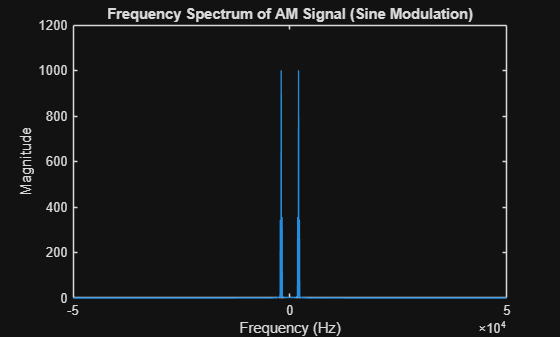


%% FREQUENCY SPECTRUM USING FFT

N = length(t);
f = (-N/2:N/2-1)*(fs/N);

AM_fft = fftshift(abs(fft(am1)));

figure
plot(f,AM_fft)
title('Frequency Spectrum of AM Signal (Sine Modulation)')
xlabel('Frequency (Hz)')
ylabel('Magnitude')

m5 = randn(size(t));     % Noise modulation
m6 = sin(2*pi*fm*t) + 0.5*sin(2*pi*3*fm*t); % multi-tone